# dinteg_lri

performs the integral double of a sampled signal.

## Syntax

pos=dinteg_lri(acc,freq)

## Description

`pos=dinteg_lri(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz. Previous to the second integral, a lineal resetting mechanism is applied to the velocity by weighting linearly between 1 and 0 during the integration time *T* (LRI method). This is to ensure that *v*(*T*) = 0, a property that you want to fulfill.

				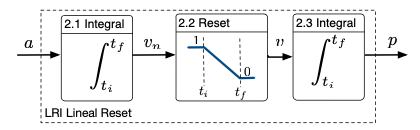

More information: 

Sabatini, A.M.; Martelloni, C.; Scapellato, S.; Cavallo, F. Assessment of walking features from foot inertial 							sensing. *IEEE Trans. Biomed. Eng. ***2005**, *52*, 486–494. 

Alvarez J., Alvarez D., Lopez A., Accelerometry-Based Distance Estimation for Ambulatory Human Motion Analysis, Sensors (2018)  n.18, 4441, 10.3390/s18124441. 						

## Examples

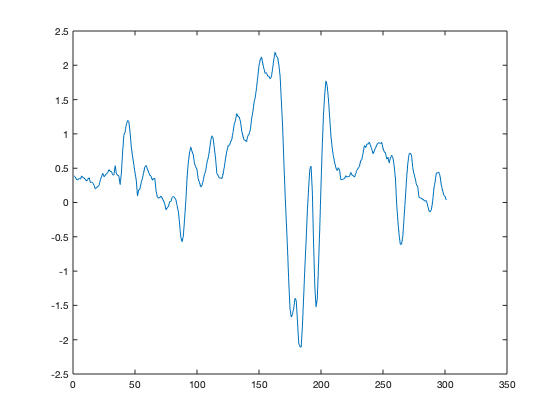

% cargamos datos de una acelerometro que sube y vuelve a la posicion de
% reposo:
filename='../simur_data/SAL.log';
datosxs=load(filename);
acc=datosxs(100:400,2)+9.8;
plot(acc);

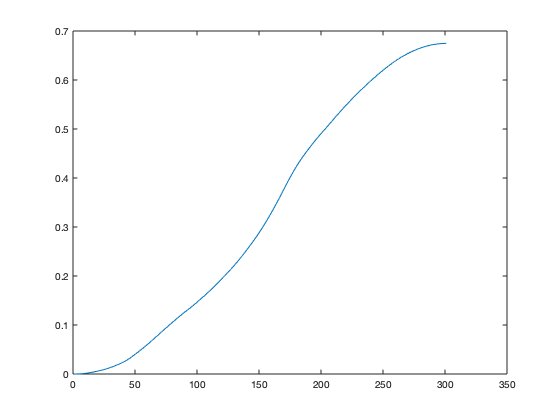

plot(dinteg_lri(acc,100));